# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 -0.6 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.6 0.35])*axang2tform([0 1 0 -pi/4]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

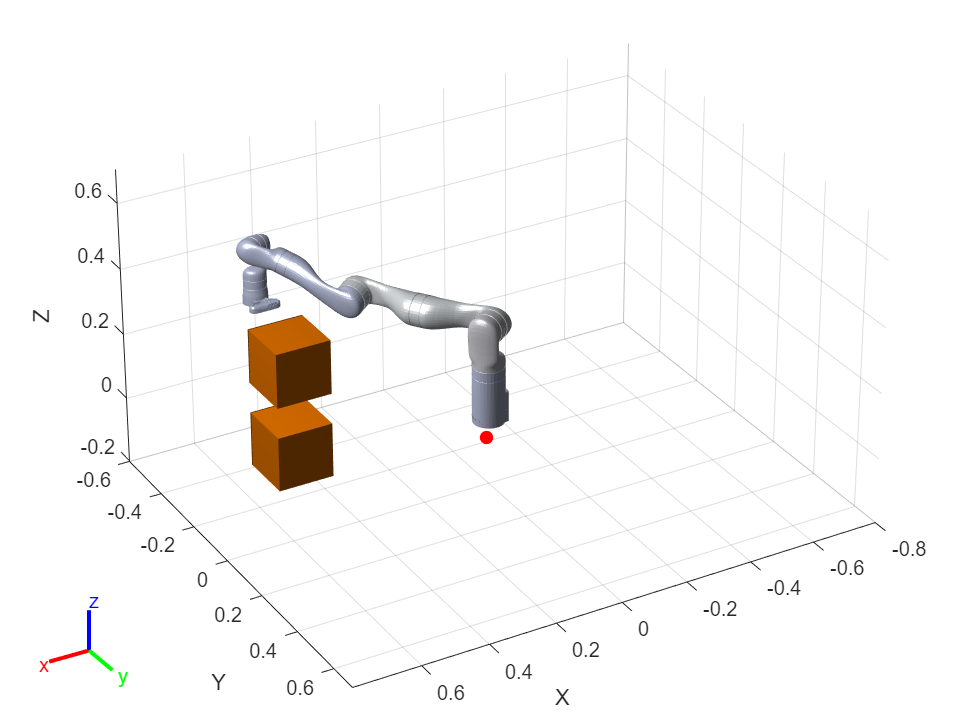

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

iter = 1

Elapsed time is 1.292916 seconds.


Qtheta = 318.8519

RAR = 33.0113

iter = 2

Elapsed time is 1.287938 seconds.


Qtheta = 320.9681

RAR = 33.0188

iter = 3

Elapsed time is 1.281140 seconds.


Qtheta = 318.7226

RAR = 33.0135

iter = 4

Elapsed time is 1.297386 seconds.


Qtheta = 315.6961

RAR = 33.0130

iter = 5

Elapsed time is 1.303488 seconds.


Qtheta = 321.5611

RAR = 33.0116

iter = 6

Elapsed time is 1.314638 seconds.


Qtheta = 322.9347

RAR = 33.0132

iter = 7

Elapsed time is 1.306748 seconds.


Qtheta = 318.2393

RAR = 33.0152

iter = 8

Elapsed time is 1.317228 seconds.


Qtheta = 317.7750

RAR = 33.0159

iter = 9

Elapsed time is 1.305646 seconds.


Qtheta = 322.1302

RAR = 33.0198

iter = 10

Elapsed time is 1.303208 seconds.


Qtheta = 316.9551

RAR = 33.0169

iter = 11

Elapsed time is 1.298765 seconds.


Qtheta = 308.2792

RAR = 33.0099

iter = 12

Elapsed time is 1.296025 seconds.


Qtheta = 288.0457

RAR = 33.0093

iter = 13

Elapsed time is 1.284266 seconds.


Qtheta = 238.2808

RAR = 33.0050

iter = 14

Elapsed time is 1.280586 seconds.


Qtheta = 246.6127

RAR = 33.0110

iter = 15

Elapsed time is 1.283022 seconds.


Qtheta = 216.0892

RAR = 33.0098

iter = 16

Elapsed time is 1.298693 seconds.


Qtheta = 180.1648

RAR = 33.0064

iter = 17

Elapsed time is 1.301757 seconds.


Qtheta = 144.8450

RAR = 33.0030

iter = 18

Elapsed time is 1.290333 seconds.


Qtheta = 114.6494

RAR = 32.9999

iter = 19

Elapsed time is 1.294793 seconds.


Qtheta = 86.1167

RAR = 32.9987

iter = 20

Elapsed time is 1.295818 seconds.


Qtheta = 72.9791

RAR = 32.9998

iter = 21

Elapsed time is 1.292357 seconds.


Qtheta = 63.7571

RAR = 33.0022

iter = 22

Elapsed time is 1.303976 seconds.


Qtheta = 47.9263

RAR = 33.0024

iter = 23

Elapsed time is 1.297434 seconds.


Qtheta = 49.8983

RAR = 33.0000

iter = 24

Elapsed time is 1.280832 seconds.


Qtheta = 47.5757

RAR = 32.9991

iter = 25

Elapsed time is 1.280317 seconds.


Qtheta = 40.5229

RAR = 33.0012

iter = 26

Elapsed time is 1.280519 seconds.


Qtheta = 38.1513

RAR = 32.9978

iter = 27

Elapsed time is 1.279987 seconds.


Qtheta = 38.1318

RAR = 32.9978

STOMP Finished.


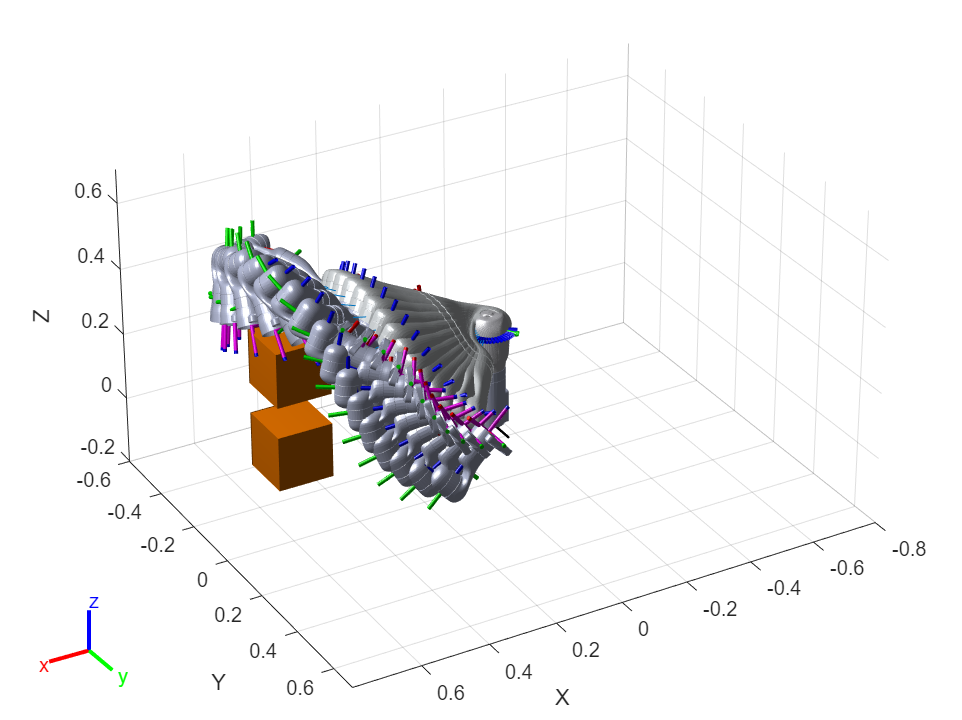

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.